# Code commenting

A colleague has recently left your development team at work. They were a great coder, but notoriously bad at commenting their work. Your boss has asked you to go through one of their scripts which contains some work on classifying hand-written letter shapes, and add comments that will help the rest of your team understand what's going on. You should add comments in your own words and you should prioritise clearly explaining what is going on to colleagues who may not have much experience of Machine Learning. It's fine if your comments go over more than one line.

The steps you should comment on, and the number of marks available for each comment are indicated below:

% add your comment here [1 mark]: ...
% clear all variables and read in the csv file data:
clear all;
data = readtable('letterdata.csv');

% add your comment here [1 mark]: ...
% set the rng to a constant value:
rng(1);

% add your comment here [1 mark]: ...
% shuffle the data to avoid patterns:
data_shuffled = data(randperm(size(data,1)), :);

% add your comment here [2 marks]: ...
% split the testing data and training data,
% the first 16000 are used for testing, the rest for training:
data_test = data_shuffled(1:1:16000, :);
data_train = data_shuffled(16001:1:end, :);

% add your comment here [2 marks]: ...
% store the testing labels in a categorical array:
test_labels = categorical(data_test{:,'letter'});
% make a copy of the testing data:
test_examples = data_test;
% delete the testing labels from the new copy of the testing data:
test_examples(:,'letter') = [];

% add your comment here [2 marks]: ...
% store the training labels in a categorical array:
train_labels = categorical(data_train{:,'letter'});
% make a copy of the training data:
train_examples = data_train;
% delete the training labels from the new copy of the training data:
train_examples(:,'letter') = [];

% add your comment here [2 marks]: ...
% train the decision tree classifier using the training examples and training labels:
% 2 comma-seperated-pairs to turn off merging of the leaves and pruning of the leaves:
m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

m =   ClassificationTree
           PredictorNames: {'xbox'  'ybox'  'width'  'height'  'onpix'  'xbar'  'ybar'  'x2bar'  'y2bar'  'xybar'  'x2ybar'  'xy2bar'  'xedge'  'xedgey'  'yedge'  'yedgex'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 4000


  Properties, Methods



% add your comment here [1 mark]: ...
% pass the trainined classifier into predict function along with the testing
% examples to test the classifier:
predictions = predict(m, test_examples);

% add your comment here [1 mark]: ...
% create a confusion matrix using the testing labels and predictions to
% visualise the performance of the classifier:
[c,order] = confusionmat(test_labels, predictions)

c =    544     5     0     1     1     1     2     7     0     0    11     6     6     0     3     0     1     3    20     1    16     0     0     5     2     0
     2   432     6    29     7    22    12    19    10     8    13     1     0     0     1     2     4    16    11     1     0     8     1     4     1     0
     0     3   435     0    12    10    23     2     2     0    11     5     1     0    11     0    10     5    10    14    11     0     1     1     0     1
     1    33     1   472     2     8     7    14     6     5     2     0     1    13    25    10     0     8    16     0     0     0     0     9     0     7
     8    16    21     1   455     5    18     0     2     4    10     7     0     0     0     0    11     5    17     1     0     2     1    12     1    23
     2    11     5     2     2   447     6     7     1     4     0     6     0     3     0    43     3     0    17    18     0    15     1     8     8     5
     3    19    18    14    21     2   431     3     0

order = 26×1 categorical array
     A 
     B 
     C 
     D 
     E 
     F 
     G 
     H 
     I 
     J 
     K 
     L 
     M 
     N 
     O 
     P 
     Q 
     R 
     S 
     T 
     U 
     V 
     W 
     X 
     Y 
     Z 



% add your comment here [2 marks]: ...
% calculate the accuracy of the classifier by dividing the number of correct
% classifications by the total number of testing examples:
p = sum(diag(c)) / sum(c(:))

p = 0.7469

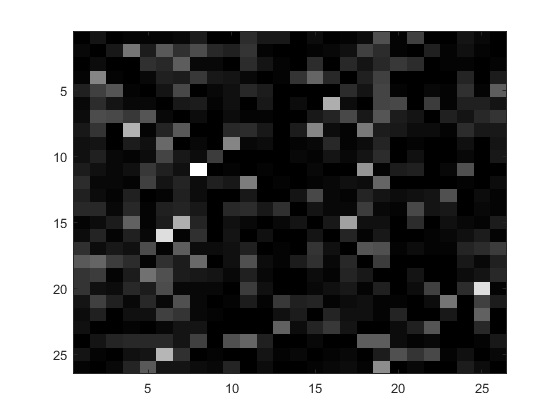


% add your comment here [2 marks]: ...
% make a copy of the confusion matrix:
c_errors = c;
% delete all the diagonal (correct) values in the matrix:
c_errors = c_errors - diag(diag(c_errors));
% create a new figure window:
figure;
% create a colour map with a grey colour scale:
colormap('gray');
% pass the new confusion matrix of incorrect data into the colour map image:
imagesc(c_errors)


% add your comment here [3 marks]: ...
% find the linear index of the highest error:
[~, m] = max(c_errors(:))

m = 193

% using the linear index of the highest error, find and store the corresponding
% x and y values in the confusion matrix:
[i,j] = ind2sub(size(c_errors), m)

i = 11

j = 8

% print out corresponding values for the location of the highest error: 
fprintf('%s mistaken for %s\n', order(i), order(j));

K mistaken for H


[Total: 20 marks]